# From antenna toolbox to Phased Array Analysis

## Dual polarization antenna

- a PCB Antenna Design has been created from this shipping example : [https://www.mathworks.com/help/releases/R2025b/antenna/ug/model-and-analyze-dual-polarized-patchmicrostrip-antenna.html](https://www.mathworks.com/help/releases/R2025b/antenna/ug/model-and-analyze-dual-polarized-patchmicrostrip-antenna.html)

- Please open PCB_AntennaDesign.mat in PCBAntennaDesigner for more details

clear;

### Load dual polarization antenna design

- created using PCBAntennaDesigner App

load dualPolarizedAntennaDesign.mat;

### Settings

c       = physconst('LightSpeed');
fc      = 2.4e9;
lambda  = freq2wavelen(fc,c);

- Array specifications

numRows = 8;
numCols = 8;
lattice = "rectangular";

- Adjust Mesh

meshconfig(dualPolarizedAntenna,'manual');

ans = struct with fields:
     NumTriangles: 0
    NumTetrahedra: 0
         NumBasis: []
    MaxEdgeLength: []
    MinEdgeLength: []
       GrowthRate: []
         MeshMode: 'manual'


mesh(dualPolarizedAntenna,"MaxEdgeLength",0.006, "MinEdgeLength",0.004, "GrowthRate",0.7)

figure;
mesh(dualPolarizedAntenna)

az = -180:5:180;
el = -90:5:90;

tic;
figure
pattern(dualPolarizedAntenna,fc,az,el);
toc

Elapsed time is 126.082605 seconds.


AESA = phased.URA(...
    "Element",dualPolarizedAntenna,...
    "Size",[numRows, numCols],...
    "ElementSpacing",lambda/2, ...
    "Lattice",lattice);

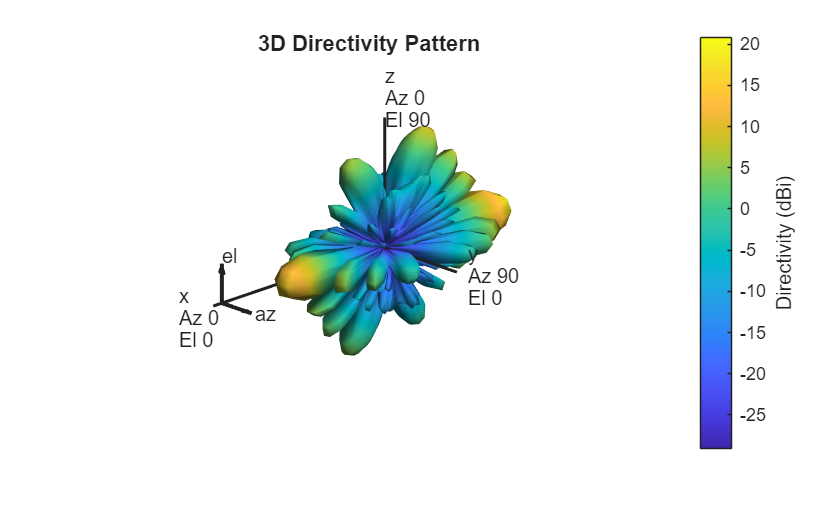

az = -180:5:180;
el = -90:5:90;
pattern(AESA,fc,az,el)